# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 30-May-2020 22:55:08

## Setup the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 9);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:I1251";

% Specify column names and types
opts.VariableNames = ["date", "gas92", "gas95", "gas98", "diesel", "Var6", "Var7", "A", "B"];
opts.SelectedVariableNames = ["date", "gas92", "gas95", "gas98", "diesel", "A", "B"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "char", "char", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var6", "Var7"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var6", "Var7"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "date", "InputFormat", "");

% Import the data
prices = readtable("油價.xlsx", opts, "UseExcel", false)

prices = 1250×7 table
       date        gas92    gas95    gas98    diesel     A       B  
    ___________    _____    _____    _____    ______    ____    ____

    26-May-2020     NaN      NaN      NaN       NaN      NaN     NaN
    25-May-2020    19.6     21.1     23.1      17.1     9893    5978
    19-May-2020     NaN      NaN      NaN       NaN      NaN     NaN
    18-May-2020    19.1     20.6     22.6      16.3     9093    5178
    13-May-2020     NaN      NaN      NaN       NaN      NaN     NaN
    12-May-2020     NaN      NaN      NaN       NaN      NaN     NaN
    11-May-2020    18.2     19.7     21.7      15.4     8193    4278
    06-May-2020     NaN      NaN      NaN       NaN      NaN     NaN
    04-May-2020    16.2     17.7     19.7      13

## Clear temporary variables

clear opts

% 預處理
prices = prices(~any(ismissing(prices), 2), :);
prices.A = prices.A ./ 1000;
prices.B = prices.B ./ 1000;
prices = flipud(prices)

prices = 589×7 table
       date        gas92    gas95    gas98    diesel      A        B  
    ___________    _____    _____    _____    ______    _____    _____

    14-Jul-1999      16       17       18      12.4     6.297    3.997
    11-Aug-1999    16.4     17.4     18.4      12.7     6.582    4.195
    01-Sep-1999    16.4     17.4     18.4      12.7     6.582    4.195
    10-Nov-1999    16.8     17.8     18.8        13     6.868    4.397
    08-Dec-1999    17.2     18.2     19.2      13.4     7.249    4.641
    16-Feb-2000    17.6     18.6     19.6      13.8      7.63    4.885
    29-Mar-2000    18.1     19.1     20.1      14.2     8.011    5.129
    21-Jun-2000    18.6     19.6     20.6      14.5     8.297    5.312
    02-Aug-2000    18.3     19

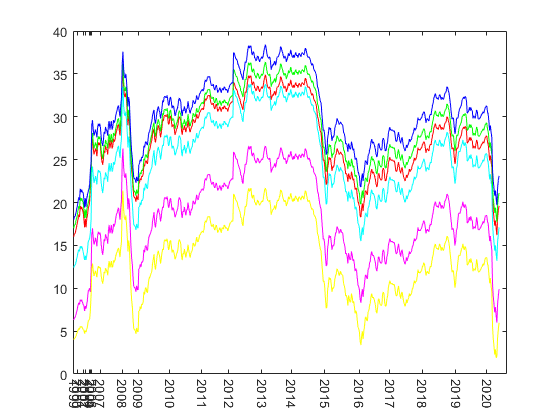

% 全部
title('歷年油價');
xlabel('年分');
ylabel('每公升價格(NTD)');
plot(prices.gas92, 'r');
hold on;
plot(prices.gas95, 'g');
hold on;
plot(prices.gas98, 'b');
hold on;
plot(prices.diesel, 'c');
hold on;
plot(prices.A, 'm');
hold on;
plot(prices.B, 'y');
[y, i] = unique(prices.date.Year);
xticks(i);
xticklabels(y);
xtickangle(270);

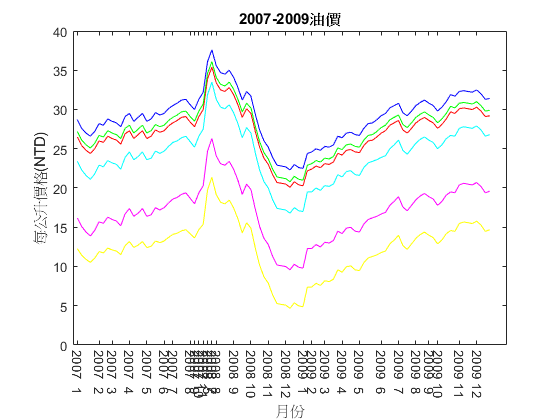

plotYear(prices, [2007 2009])

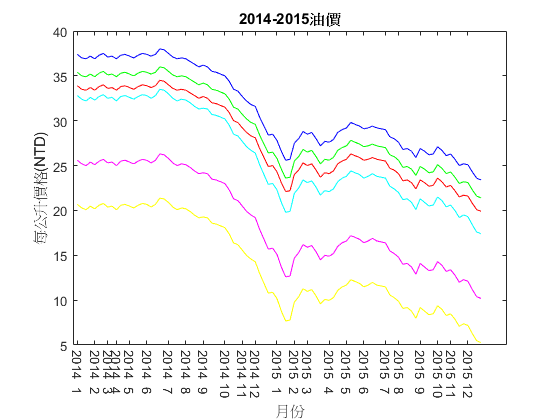

plotYear(prices, [2014 2015])

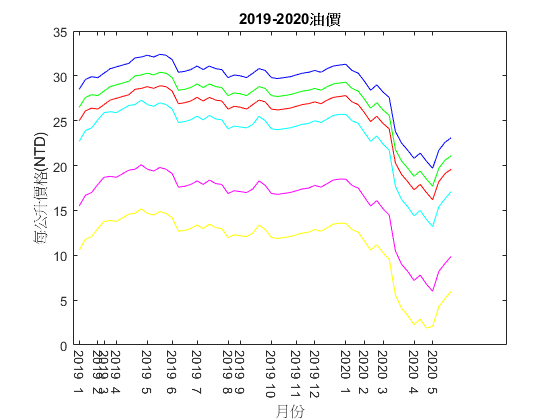

plotYear(prices, [2019 2020])

function plotYear(prices, years)
clf
i = find(ismember(prices.date.Year, years(1):years(end)));
plot(prices.gas92(i), 'r');
hold on;
plot(prices.gas95(i), 'g');
hold on;
plot(prices.gas98(i), 'b');
hold on;
plot(prices.diesel(i), 'c');
hold on;
plot(prices.A(i), 'm');
hold on;
plot(prices.B(i), 'y');

title(sprintf('%d-%d油價', years));
xlabel('月份');
ylabel('每公升價格(NTD)');

dates = strcat(num2str(prices.date.Year(i)), " ", num2str(prices.date.Month(i)));
[dates, i] = unique(dates);
xticks(i);
xticklabels(dates);
xtickangle(270);
end